Problema obligatorie

% a), b)
clear 
syms x f(x) a b
R=Rombergsym(f,a,b,3)

$$R = \begin{array}{l} \left(\begin{array}{ccc} -\sigma_{4} & 0 & 0\\ -\frac{\sigma_{2}}{2}-\frac{\sigma_{4}}{2} & -\frac{\sigma_{3}}{3}-\frac{\sigma_{4}}{3} & 0\\ -\frac{\sigma_{2}}{4}-\frac{\sigma_{5}\,\sigma_{1}}{2}-\frac{\sigma_{4}}{4} & -\frac{\sigma_{2}}{6}-\frac{2\,\sigma_{5}\,\sigma_{1}}{3}-\frac{\sigma_{4}}{6} & -\frac{\sigma_{3}}{15}-\frac{32\,\sigma_{5}\,\sigma_{1}}{45}-\frac{7\,\sigma_{5}\,\left(f\left(a\right)+f\left(b\right)\right)}{45} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=f\left(\frac{a}{4}+\frac{3\,b}{4}\right)+f\left(\frac{3\,a}{4}+\frac{b}{4}\right)\\ \sigma_{2}=f\left(\frac{a}{2}+\frac{b}{2}\right)\,\left(a-b\right)\\ \sigma_{3}=2\,f\left(\frac{a}{2}+\frac{b}{2}\right)\,\left(a-b\right)\\ \sigma_{4}=\sigma_{5}\,\left(f\left(a\right)+f\left(b\right)\right)\\ \sigma_{5}=\frac{a}{2}-\frac{b}{2} \end{array}$$

disp(prod(factor(simplify(R(2,2)))))

$$-\frac{\left(a-b\right)\,\left(4\,f\left(\frac{a}{2}+\frac{b}{2}\right)+f\left(a\right)+f\left(b\right)\right)}{6}$$

% Coloana 2 e formula lui Simpson
disp(prod(factor(simplify(R(3,2)))))

$$-\frac{\left(a-b\right)\,\left(2\,f\left(\frac{a}{2}+\frac{b}{2}\right)+4\,f\left(\frac{a}{4}+\frac{3\,b}{4}\right)+4\,f\left(\frac{3\,a}{4}+\frac{b}{4}\right)+f\left(a\right)+f\left(b\right)\right)}{12}$$

% Coloana 3 e formula Boole-Villarceau
disp(prod(factor(R(3,3))))

$$-\frac{\left(a-b\right)\,\left(12\,f\left(\frac{a}{2}+\frac{b}{2}\right)+32\,f\left(\frac{a}{4}+\frac{3\,b}{4}\right)+32\,f\left(\frac{3\,a}{4}+\frac{b}{4}\right)+7\,f\left(a\right)+7\,f\left(b\right)\right)}{90}$$

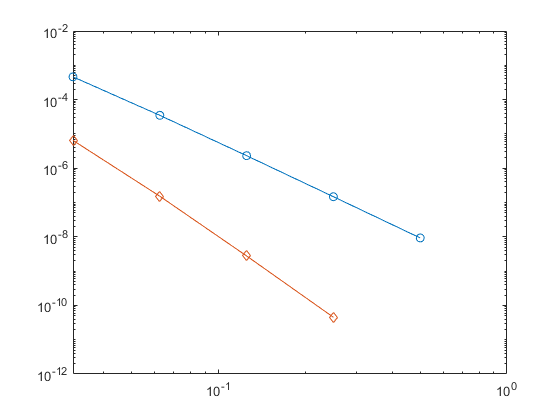

% c)
clear
syms x
format long
ve=double(int(log(x),x,1,2)); % valoarea exactă a integralei
a=1;
b=2;
n=6;
R=Rombergit(@log,1,2,n);
err2=abs(R(2:end,2)-ve); % eroare pentru formula Simpson
err3=abs(R(3:end,3)-ve); % eroare pentru formula Boole-Villarceau
h=(b-a)*2.^(0:-1:(-n+1));

loglog(h(end:-1:2),err2,'-o',h(end:-1:3),err3,'-d')